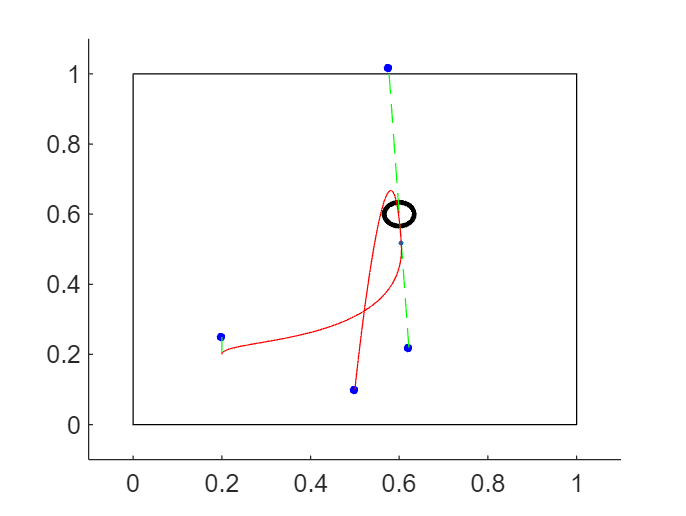

clear; close all;
hold on

table_length = 2;
table_width = 1;
x_goal = 0.52;
puck_plus_mallet_rad = 0.05 + 0.03175; %m

xcoeffs = [];
ycoeffs = [];

x_puck = 0.6;
y_puck = 0.6;

x_initial = 0.2;
y_initial = 0.2;

vx_initial = 0;
vy_initial = 0.5;

vf = [x_goal - x_puck; table_length - y_puck];
vf_magnitude = 3;

intercept_point = [x_puck; y_puck]-vf./norm(vf) .* puck_plus_mallet_rad;

plot(intercept_point(1), intercept_point(2), ".")

viscircles([x_puck, y_puck],0.0675/2,'LineStyle','-','Color','black');
rectangle('position',[0 0 1 1])

xlim([-0.1 1.1])
ylim([-0.1 1.1])

%%First Segment
q0 = [x_initial; y_initial];
v0 = [vx_initial; vy_initial];

q3 = intercept_point;
v3 = vf/norm(vf)*vf_magnitude;

t1 = 0.3;

q1 = q0 + v0.*t1/3;
q2 = q3 - v3.*t1/3;


B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

%Return Path
q0 = q3;
v0 = v3;

q3 = [0.5;0.1];
v3 = [0;0];
t2 = 0.5;

q1 = q0 + v0.*t2/3;
q2 = q3 - v3.*t2/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')